# Day 7 - Circles, Fields, and Potentials

## Question 18

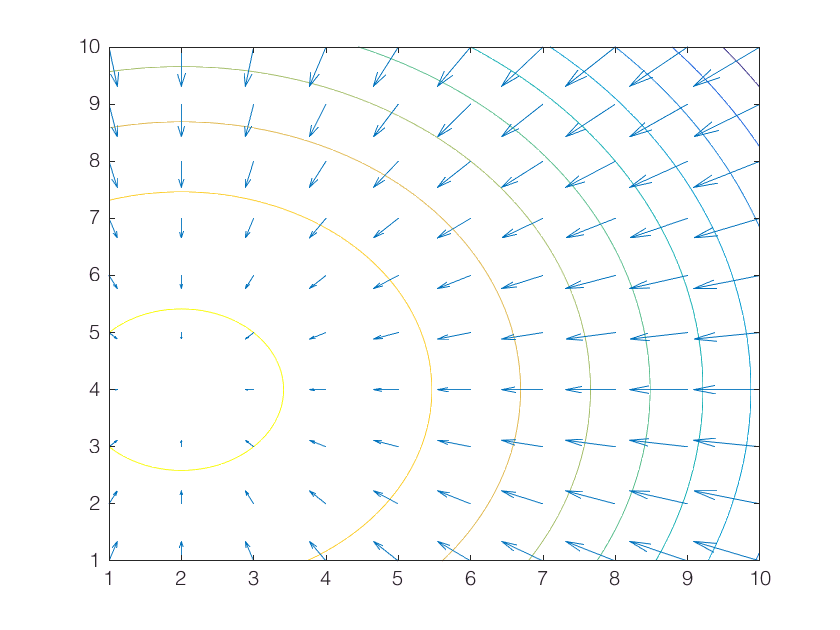


%Change these ranges and point spacings to make nice figures
[X,Y] = meshgrid([1:0.1:10],[1:0.1:10]);
[X1,Y1] = meshgrid([1:1:10],[1:1:10]);

%Define your function below.  Don't forget to specify element by element
%operations.
syms x y
f = 12-(x-2).^2 -(y-4).^2;

%This takes the gradient of your function
g = gradient(f,[x,y]);

%These lines of code make nice plots.  Look at documentation to adjust
%plotting parameters as you like.
hold off
contour(X,Y,subs(f,[x,y],{X,Y}))

G1 = subs(g(1),[x,y],{X1,Y1});
G2 = subs(g(2),[x,y],{X1,Y1});
hold on
quiver(X1,Y1,G1,G2)

## Question 19

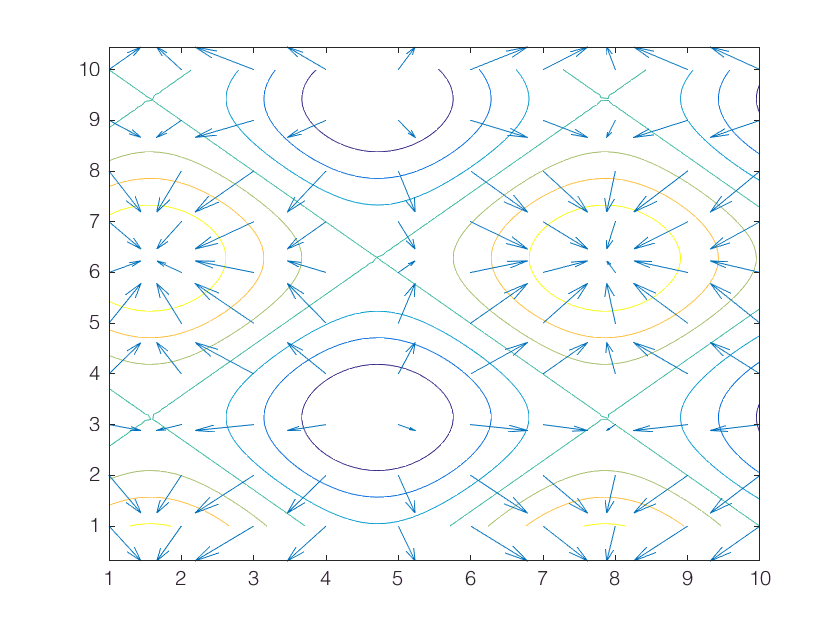

clf
%Change these ranges and point spacings to make nice figures
[X,Y] = meshgrid([1:0.1:10],[1:0.1:10]);
[X1,Y1] = meshgrid([1:1:10],[1:1:10]);

%Define your function below.  Don't forget to specify element by element
%operations.
syms x y
% f = 12-(x-2).^2 -(y-4).^2;
f = sin(x) + cos(y);

%This takes the gradient of your function
g = gradient(f,[x,y]);

%These lines of code make nice plots.  Look at documentation to adjust
%plotting parameters as you like.
hold off
contour(X,Y,subs(f,[x,y],{X,Y}))

G1 = subs(g(1),[x,y],{X1,Y1});
G2 = subs(g(2),[x,y],{X1,Y1});
hold on
quiver(X1,Y1,G1,G2)

## Question 20

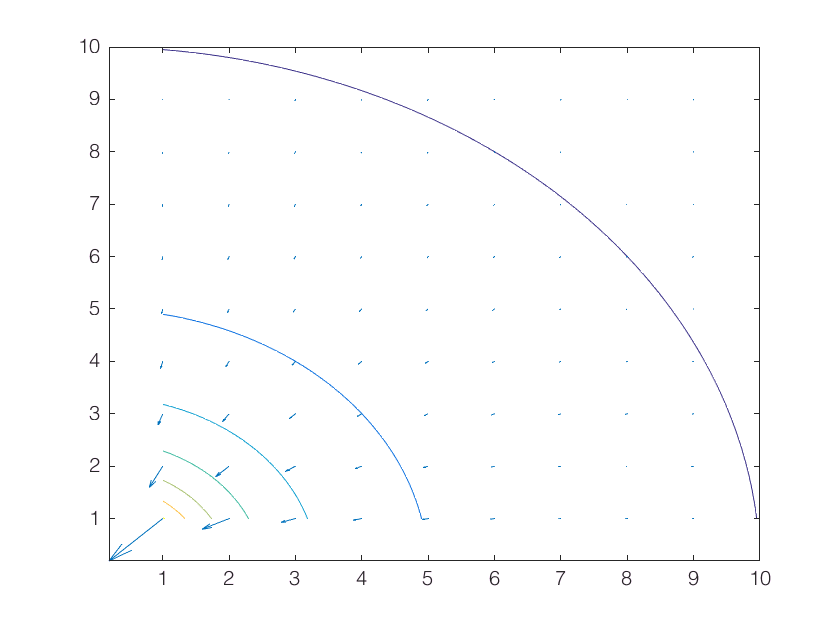

clf
%Change these ranges and point spacings to make nice figures
[X,Y] = meshgrid([1:0.1:10],[1:0.1:10]);
[X1,Y1] = meshgrid([1:1:10],[1:1:10]);

%Define your function below.  Don't forget to specify element by element
%operations.
syms x y
r = [x, y];
f = 1/norm(r);
% f = sin(x) + cos(y);

%This takes the gradient of your function
g = gradient(f,[x,y]);

%These lines of code make nice plots.  Look at documentation to adjust
%plotting parameters as you like.
hold off
contour(X,Y,subs(f,[x,y],{X,Y}))

G1 = subs(g(1),[x,y],{X1,Y1});
G2 = subs(g(2),[x,y],{X1,Y1});
hold on
quiver(X1,Y1,G1,G2)

## Question 21- 1

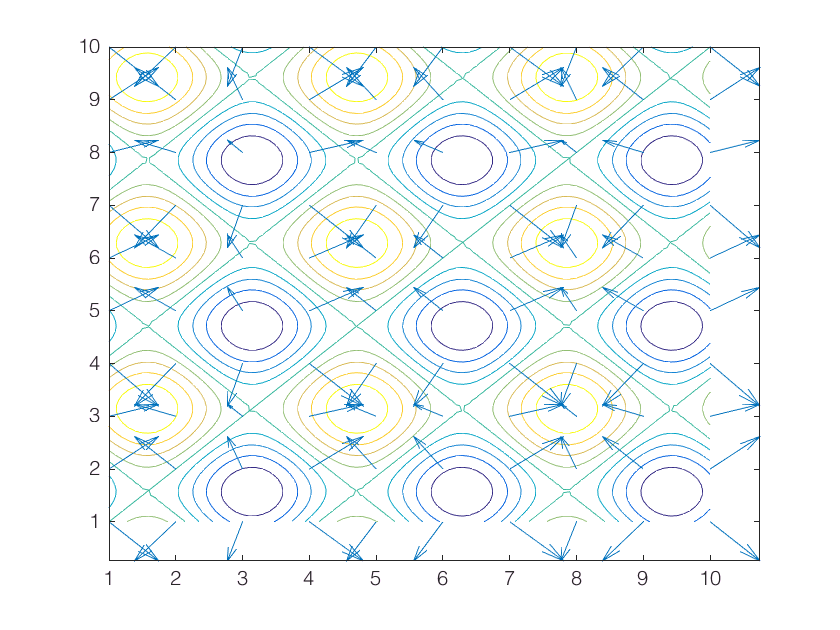

clf
%Change these ranges and point spacings to make nice figures
[X,Y] = meshgrid([1:0.1:10],[1:0.1:10]);
[X1,Y1] = meshgrid([1:1:10],[1:1:10]);

%Define your function below.  Don't forget to specify element by element
%operations.
syms x y
f = sin(x)^2+cos(y)^2;

%This takes the gradient of your function
g = gradient(f,[x,y]);

%These lines of code make nice plots.  Look at documentation to adjust
%plotting parameters as you like.
hold off
contour(X,Y,subs(f,[x,y],{X,Y}))

G1 = subs(g(1),[x,y],{X1,Y1});
G2 = subs(g(2),[x,y],{X1,Y1});
hold on
quiver(X1,Y1,G1,G2)

## Question 21-2

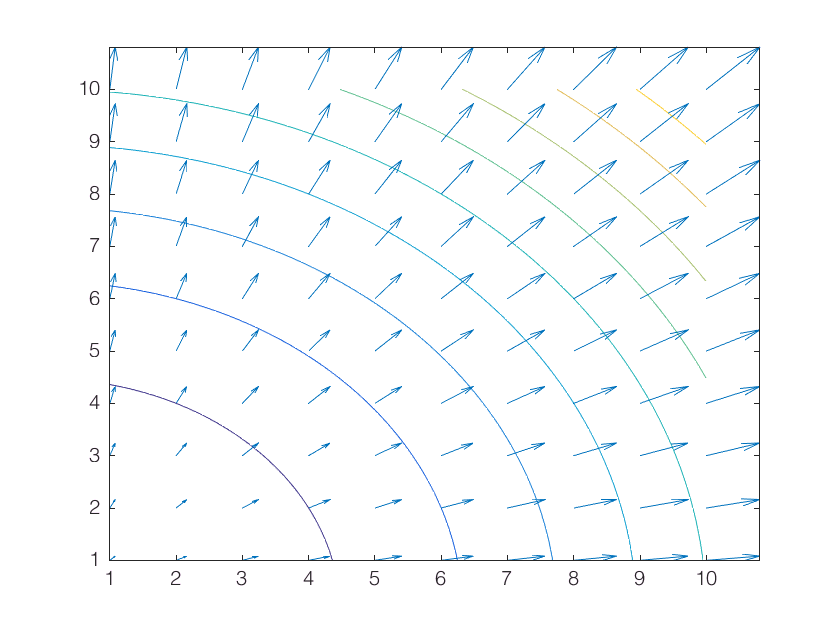

clf
%Change these ranges and point spacings to make nice figures
[X,Y] = meshgrid([1:0.1:10],[1:0.1:10]);
[X1,Y1] = meshgrid([1:1:10],[1:1:10]);

%Define your function below.  Don't forget to specify element by element
%operations.
syms x y
f = x^2+y^2;

%This takes the gradient of your function
g = gradient(f,[x,y]);

%These lines of code make nice plots.  Look at documentation to adjust
%plotting parameters as you like.
hold off
contour(X,Y,subs(f,[x,y],{X,Y}))

G1 = subs(g(1),[x,y],{X1,Y1});
G2 = subs(g(2),[x,y],{X1,Y1});
hold on
quiver(X1,Y1,G1,G2)

## Question 31

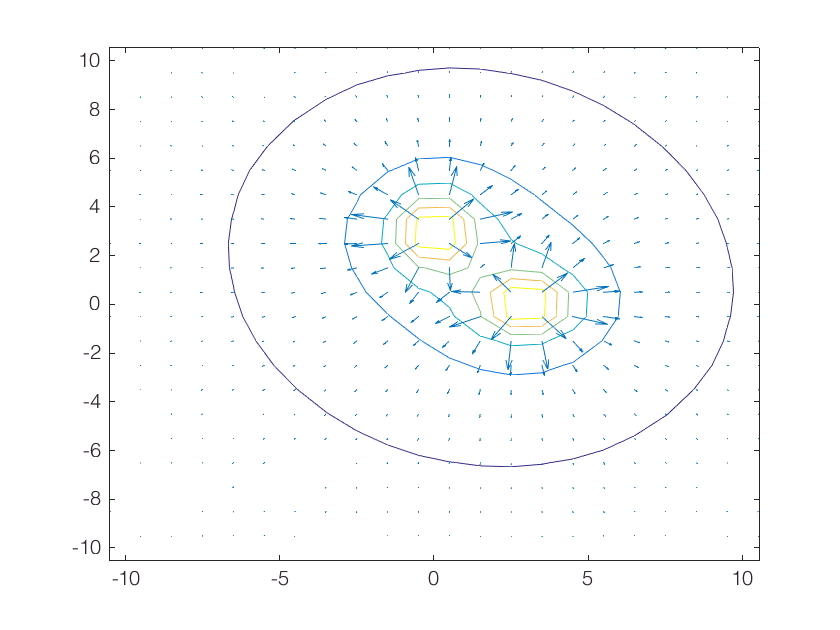

clf

[px,py]=meshgrid(-10.5:1:10.5,-10.5:1:10.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);

for i=1:xlim
    for j=1:ylim
 
dVx = @(x)  1./sqrt((px(i,j)-x).^2 + py(i,j).^2);
dVy = @(y)  1./sqrt((px(i,j)).^2 + (py(i,j)-y).^2);
V(i,j) = integral(dVx,2,4) + integral(dVy,2,4);
    end
end

hold off
contour(px,py,V)
[Ex,Ey] = gradient(V);
hold on
quiver(px,py,-Ex,-Ey)

## Question 32

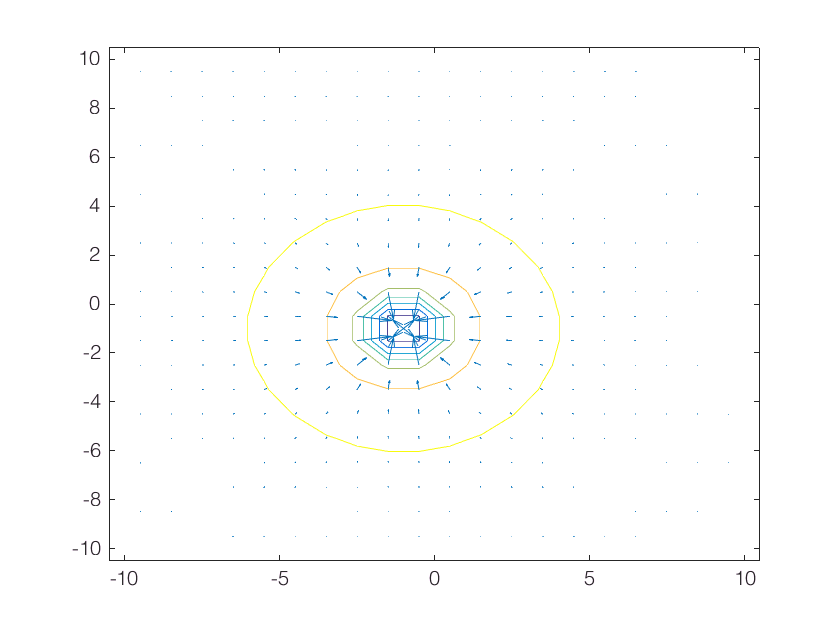

clf

[px,py]=meshgrid(-10.5:1:10.5,-10.5:1:10.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);

for i=1:xlim
    for j=1:ylim
    V(i,j) = -1./sqrt((px(i,j)+1).^2 + (py(i,j)+1).^2);
    end
end

hold off
contour(px,py,V)
[Ex,Ey] = gradient(V);
hold on
quiver(px,py,-Ex,-Ey)

## Question 33

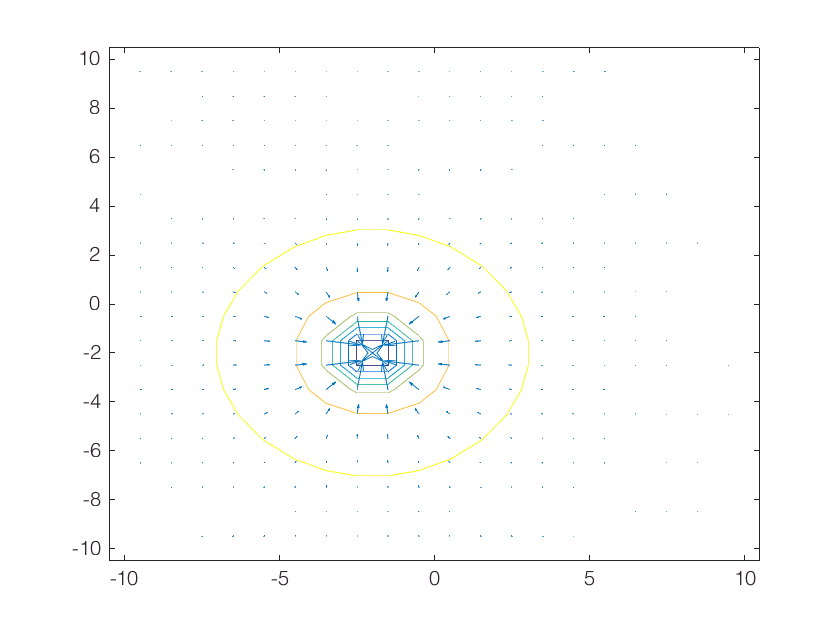

clf
[px,py]=meshgrid(-10.5:1:10.5,-10.5:1:10.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);

for i=1:xlim
    for j=1:ylim
    V(i,j) = -1./sqrt((px(i,j)+2).^2 + (py(i,j)+2).^2);
    end
end

hold off
contour(px,py,V)
[Ex,Ey] = gradient(V);
hold on
quiver(px,py,-Ex,-Ey)

## Question 34

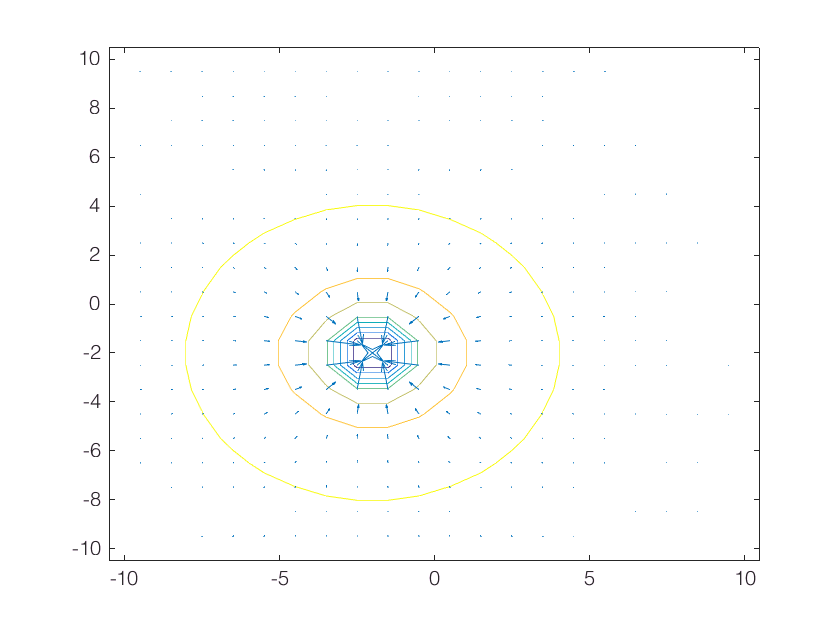

clf
[px,py]=meshgrid(-10.5:1:10.5,-10.5:1:10.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);

for i=1:xlim
    for j=1:ylim
    V(i,j) = -3./sqrt((px(i,j)+2).^2 + (py(i,j)+2).^2);
    end
end

hold off
contour(px,py,V)
[Ex,Ey] = gradient(V);
hold on
quiver(px,py,-Ex,-Ey)

clf
[px,py]=meshgrid(-10.5:1:10.5,-10.5:1:10.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);

for i=1:xlim
    for j=1:ylim
    V(i,j) = -1./sqrt((px(i,j)+1).^2 + (py(i,j)+1).^2);
    end
end

hold off
contour(px,py,V)
[Ex,Ey] = gradient(V);
hold on
quiver(px,py,-Ex,-Ey)

## Question 35

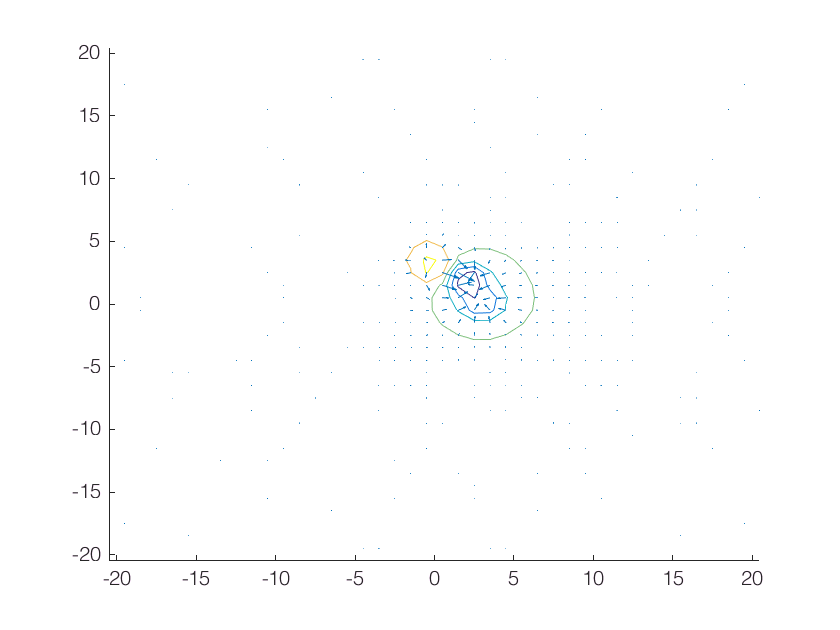

clear;
clf;

%edit your ranges to display here.  important to not include the actual
%location of your object in this grid of points or it will give you
%infinities

[px,py]=meshgrid(-20.5:1:20.5,-20.5:1:20.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);



for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
dVx = @(x)  -1./sqrt((px(i,j)-x).^2 + py(i,j).^2);
dVy = @(y)  1./sqrt((px(i,j)).^2 + (py(i,j)-y).^2);
pt = -3./sqrt((px(i,j)-2).^2 + (py(i,j)-2).^2);
V(i,j) = integral(dVx,(3 - 0.5*2),(3 + 0.5*2)) + integral(dVy,(3 - 0.5*2),(3 + 0.5*2)) + pt;
    end
end

hold off
hold on;
contour(px,py,V)
[Ex,Ey] = gradient(V);
hold on
quiver(px,py,-Ex,-Ey)
hold off;